# Jouons quelques notes avec Matlab

% File SIS-TD-Synthetiseur.mlx

clear all; close all;
Fs = 8000;  % sampling frequency
D =  0.5;   % note duration
D=0.5

D = 0.5000

Te = 1/Fs;        % sampling period
N = round(D/Te);  % number of samples in note duration 
n = Te*(0:N-1);

## Création des notes

Each note corresponds to a pure frequency.


$$\matrix{
\text{Note}  &\text{Do3}    	& \text{Ré3} 	&\text{Mi3} 	&\text{Fa3}     &\text{Sol3}  &\text{La3}  &\text{Si3}   \cr
                  &\text{C3}    	& \text{D3} 	&\text{E3} 	&\text{F3}     &\text{G3}  &\text{A3}  &\text{B3}   \cr
\text{Frequency} &261.6Hz &293.7Hz &329.6Hz  &349.6Hz &391.9Hz &440.0Hz &493.9Hz 		\cr
\text{Note}  &\text{Do4}    	& \text{Ré4} 	&\text{Mi4} 	&\text{Fa4}     &\text{Sol4}  &\text{La4}  &\text{Si4}   \cr
                    &\text{C4}    	& \text{D4} 	&\text{E4} 	&\text{F4}     &\text{G4}  &\text{A4}  &\text{B4}   \cr
\text{Frequency} &523.2Hz &587.4Hz &659.2Hz  &699.2Hz &783.8Hz &880.0Hz &987.8Hz 		\cr
}$$


octave  = [ 261.6, 293.7, 329.6, 349.6, 391.9, 440.0, 493.9 ];
kb = [ octave; 2*octave ]; % keybord , 2 octaves ;
freqs = [octave 2*octave]'; % f= vector of all frequencies

## Envelope des notes

env0=ones(1,N);
env1 = exp(-n/(D/2)); % envelope of the note : damped exponential

Other envelopes are possible, your imagination is unlimited...

k=8.8% number of wave bellies in the duration of a note

k = 8.8000

env3 = abs(sin(2*pi*k/D*n)).*exp(-n/(D/2));
env4 = abs(cos(2*pi*k/D*n)).*exp(-n/(D/2));
env5= abs(sin(2*pi*k/D*n));
env6 = 0.5*(1+sign(sin(2*pi*k/D*n))).*exp(-n/(D/2));
env7 = exp(-n.*(2+sin(2*pi*k/D*n))/(D/2));

A classical way in music synthetiser is to use de ADSR envelope.

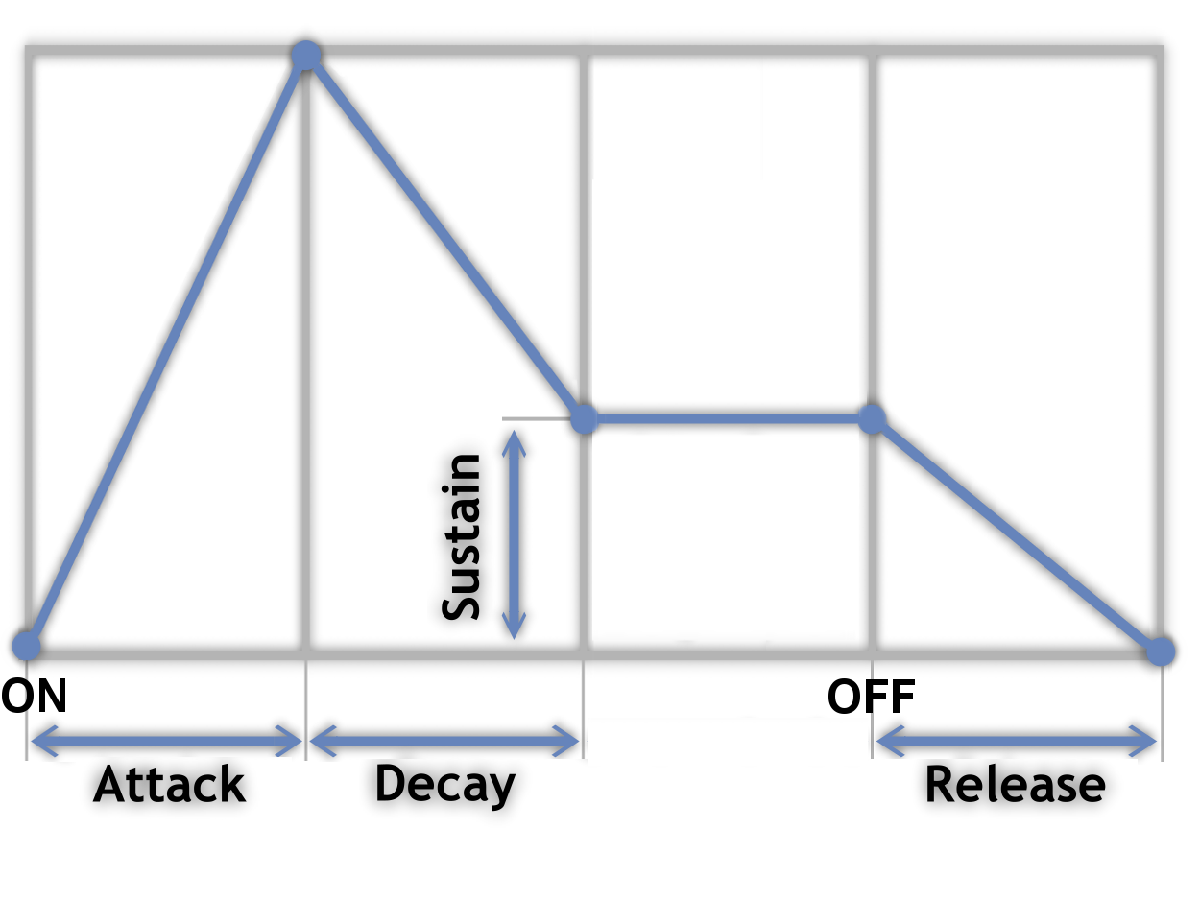

Constrain to respect:     Tattack  < Tdecay < Trelease <1 and  0 < heightsustain <1 

Tattack=floor(1/8*N)

Tattack = 500

Tdecay=floor(1/3*N)

Tdecay = 1333

Trelease=floor(3/4*N)

Trelease = 3000

heightsustain=0.3

heightsustain = 0.3000

[i,env8]=SoundEnvelope(N,Tattack,Tdecay,heightsustain,Trelease);

You juste have to choose the envelope you want:

env=env8;
%env=env3;
%env=env8.*env3;
figure;
stem(i,env);title('envelope of the note')

## Jouons la gamme

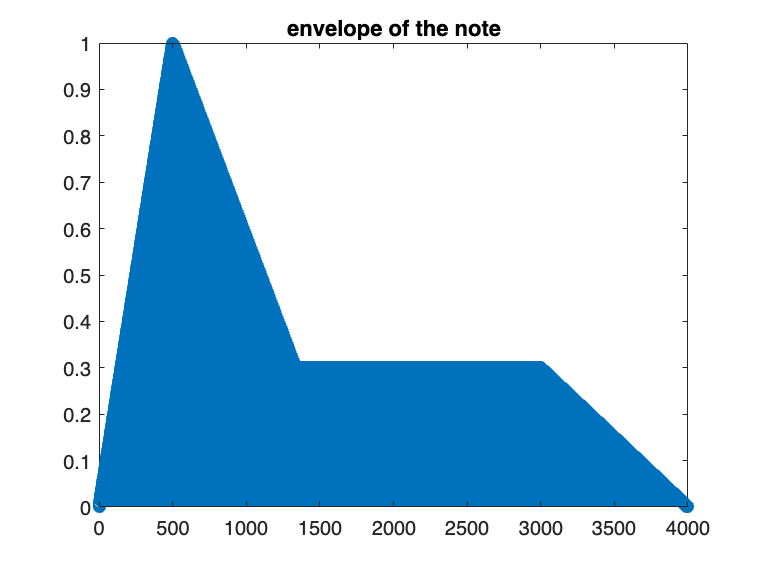

gamme = [];        
gamme_m = [];        
for k = 1 : length(freqs)
    note(k,:) = sin(2*pi*freqs(k)*n);
    gamme = [gamme note(k,:)];
    note_m(k,:) = env.*sin(2*pi*freqs(k)*n);
    gamme_m = [gamme_m note_m(k,:)];  
end

tiledlayout(3,1); 

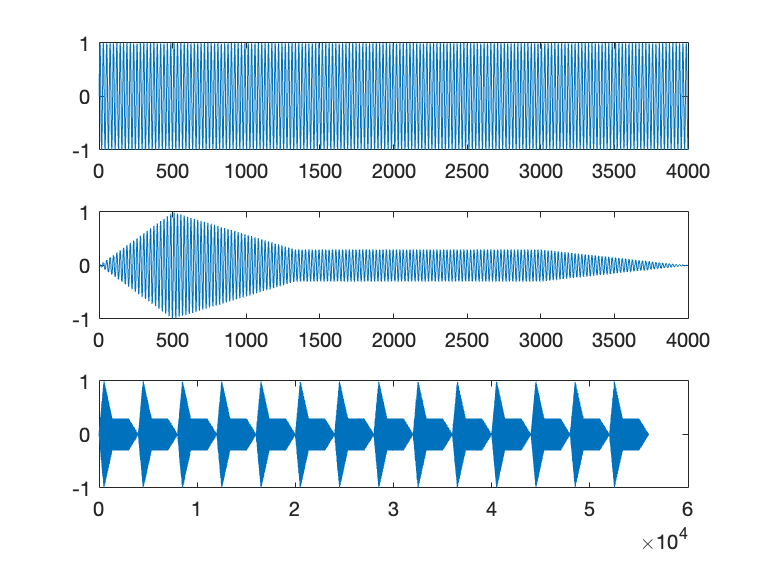

nexttile ; plot(note(4,:))
nexttile ; plot(note_m(4,:));
nexttile ; plot(gamme_m)


%soundsc(gamme,Fs);
soundsc(gamme_m,Fs);
pause( D * (length(freqs)+1) );


## Jouons un petit morceau

myfreqs = [ kb(1,5) kb(1,5) kb(1,6) kb(1,5) kb(2,1) kb(1,7) ...
            kb(1,5) kb(1,5) kb(1,6) kb(1,5) kb(2,2) kb(1,2) ...
            kb(1,5) kb(1,5) kb(2,5) kb(2,3) kb(2,1) kb(1,7) kb(1,6) ...
            kb(2,4) kb(2,4) kb(2,3) kb(2,1) kb(2,2) kb(2,1) ];
mysong = [];        
for k = 1 : length(myfreqs)
    x = env .* sin( 2*pi*myfreqs(k)*n );
    mysong = [ mysong x ];
end
soundsc(mysong,Fs);

## Fonctions pour construire l'enveloppe ADSR

function [n,x]=SoundEnvelope(N,Attack,Decay,Sustain,Release)
n=0:N-1;
x=zeros(size(n));
[n,x1]=Ramp(N,0,Attack,1,0);
[n,x2]=Ramp(N,Attack,Decay,-(1-Sustain),1);
[n,x3]=DiscreteRect(N,Decay,Release,Sustain);
[n,x4]=Ramp(N,Release,N-1,-Sustain,Sustain);
 x=x1+x2+x3+x4;
% figure
% hold on
% stem(n,x1,'r')
% stem(n,x2,'b')
% stem(n,x3,'g')
% stem(n,x4,'m')
end

function [n,x]=DiscreteRect(N,lim1,lim2,height)
n=0:N-1;
x=zeros(size(n));
x(n>=lim1)=height;
x(n>lim2-1)=0;
end 

function [n,x]=Ramp(N,lim1,lim2,height,offset)
n=0:N-1;
x=zeros(size(n));
x(n>=lim1)=1;
x=x.*(offset+(n-lim1)*(height/(lim2-lim1)));
x(n>lim2-1)=0;
end

